各桿件長度的數據

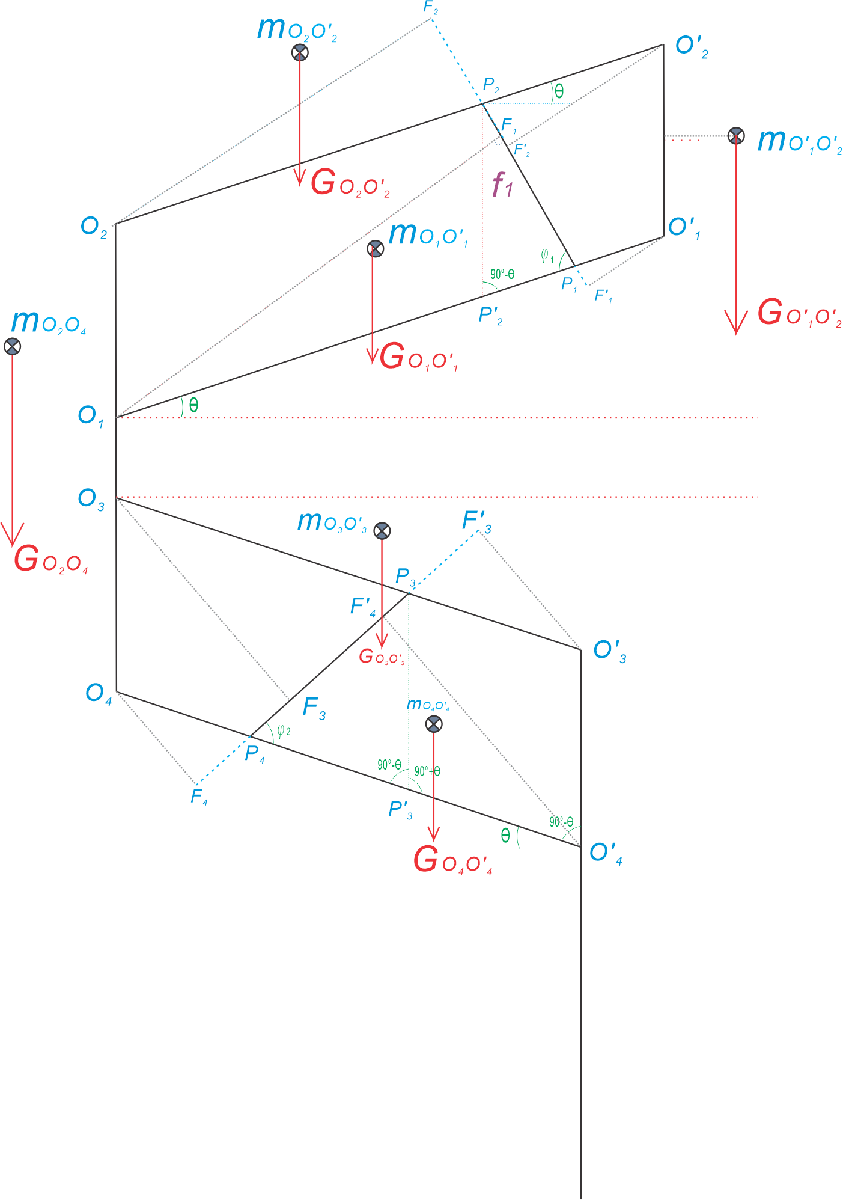

%theta=-45:1:45;  
thetad = -75:0.1:75;
phi=[];phi2=[];
%****************定義基礎結構尺寸*********************** 。
LO1O_1=762 ;   %上部下連桿長度。
LO1O2=254;     %上部豎桿長度:後端介面。
LO3O_3=647.7;  %下部上連桿長度。
LO1O3=70;      %兩齒輪間距

%O1P1=1:10:762; O2P2=0;  %上部橡皮筋固定點。
%O3P3=350; O4P4=300;    %下部橡皮筋固定點。
LO1P1=450; LO2P2=300;
LO_3P3=200;LO_4P4=350;



%*************導出其他衍生結構*******************
LO2O_2=LO1O_1;    %上部上連桿長度=上部下連桿長度。
LO_1O_2=LO1O2;    %上區山桿 : 前端介面 =後端介面。
LP2P_2=LO1O2;     %上部橡皮筋投影到豎桿的長度=上部豎桿長度。

LO4O_4=LO3O_3;    %下部下連桿長度=下部上連桿長度。
LO3O4=LO1O2;    %下部豎桿支撐點長度=上部豎桿長度。
LO_3O_4=LO3O4;    %下部豎桿支撐點長度=上部豎桿長度。
LP3P_3=LO3O4;     %下部橡皮筋投影到豎桿的長度。

%************length of elastic materials***********
LP1P2=[]; LP3P4=[];

以下開始計算與彈性材料無關的座標

thetar= deg2rad(thetad); %convert theta to radian
O_4.x = zeros(size(thetad,2)); O_4.y=zeros(size(thetad,2));%set O_4 as origin by making it a zero vector of the size of thetad
% P4.x= -LO_4P4*cos(thetar); P4.y= LO_4P4*sin(thetar); 
% P3.x= -LO_3P3*cos(thetar); P3.y= LO_3O_4 + LO_3P3*sin(thetar);
% VP3P4=[P4.x-P3.x P4.y-P3.y]; VO_4P4=[P4.x-O_4.x P4.y-O_4.y];    %two temporary vector
% LP3P4=norm(VP3P4); LO_4P4=norm(VO_4P4); %and the length of them
%phi2= acos(dot(VP3P4, VO_4P4)/(LP3P4*LO_4P4)); %use dot product to calcualte phi2
%phi2d= rad2deg(phi2); 

O3.x =-LO3O_3*cos(thetar); O3.y =LO_3O_4 + LO3O_3*sin(thetar);
O_3.x =zeros(size(thetad,2)); O_3.y=LO_3O_4+zeros(size(thetad,2));
O4.x= -LO4O_4*cos(thetar); O4.y=LO4O_4*sin(thetar);
O1.x= O3.x; O1.y= O3.y+ LO1O3;
O2.x= O1.x; O2.y=O1.y+LO1O2;
O_1.x= O1.x+LO1O_1*cos(thetar); O_1.y= O1.y+LO1O_1*sin(thetar);
O_2.x= O_1.x; O_2.y= O_1.y+LO1O2;

plotting the whole mechanism

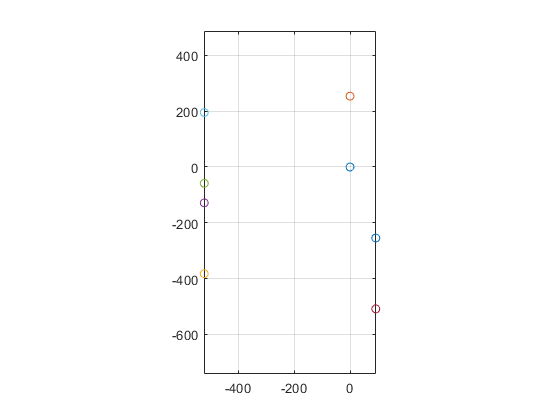

angled=-36.2; %angle in degree
ind = find(abs(thetad-angled)<0.001); %find the index of the desired theta(check "find" documentation)
plot(O_4.x(ind), O_4.y(ind), 'o'); hold on;
plot(O_3.x(ind), O_3.y(ind), 'o'); hold on;
plot(O4.x(ind), O4.y(ind), 'o'); hold on;
plot(O3.x(ind), O3.y(ind), 'o'); hold on;
plot(O1.x(ind), O1.y(ind), 'o'); hold on;
plot(O2.x(ind), O2.y(ind), 'o'); hold on;
plot(O_1.x(ind), O_1.y(ind), 'o'); hold on;
plot(O_2.x(ind), O_2.y(ind), 'o'); hold off;
grid on;
pbaspect([1 2 1]);
daspect([1 1 1]);

各桿件質心的數據︰$R$為質心和支點的距離、$\alpha$為質心和支點連線和桿件的夾角、$m$為質心

方向參考附圖

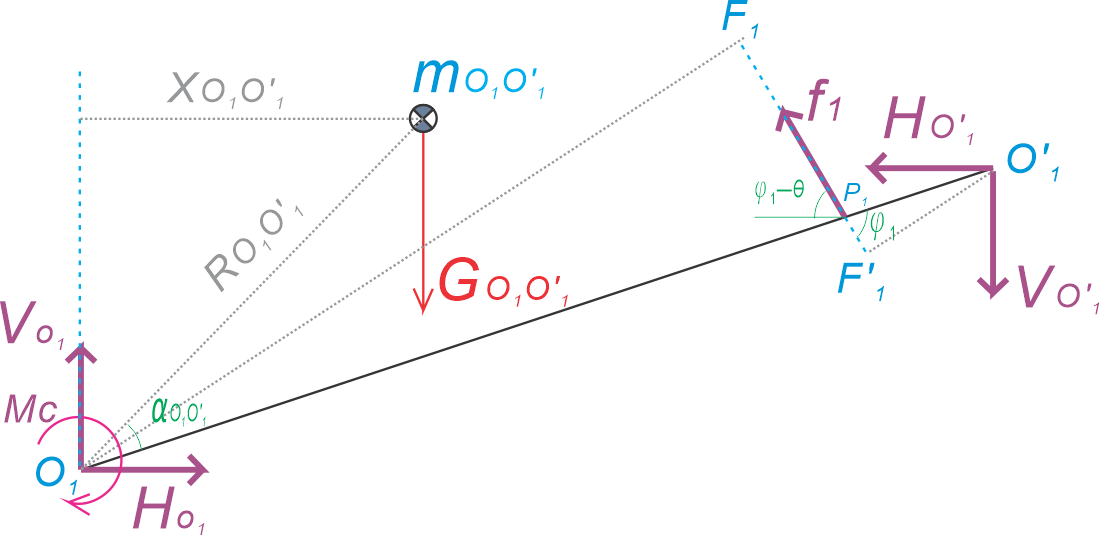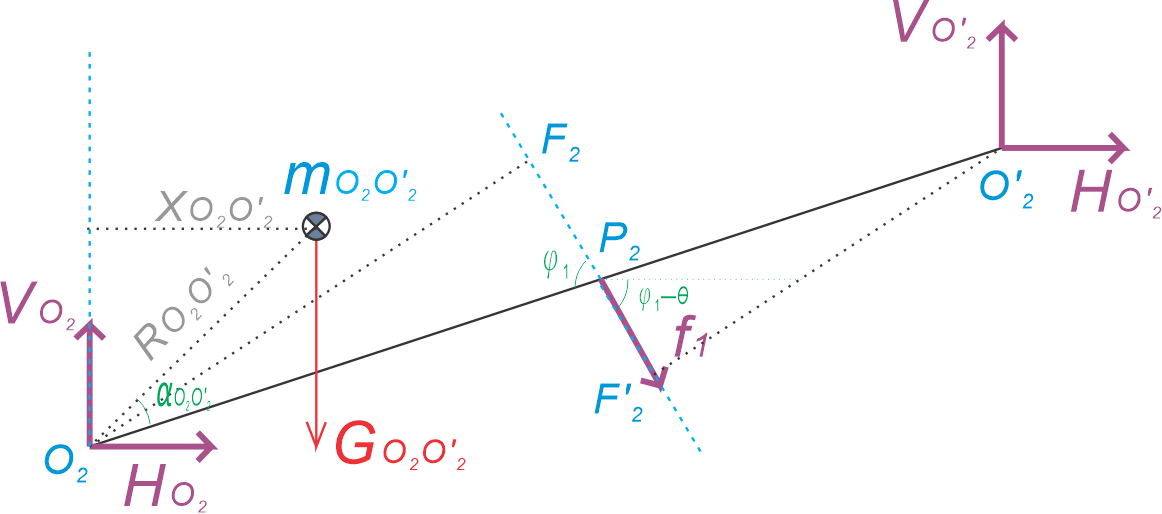

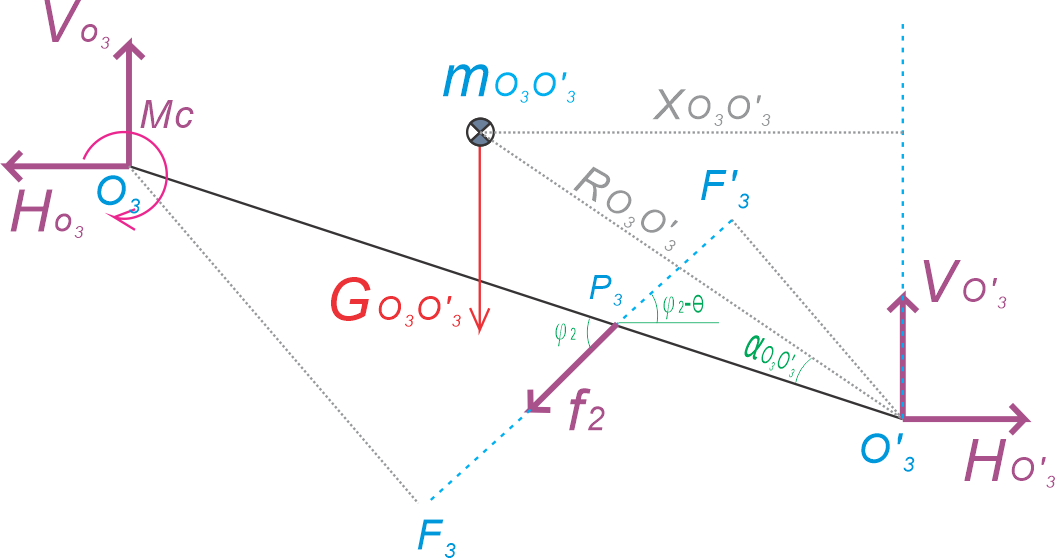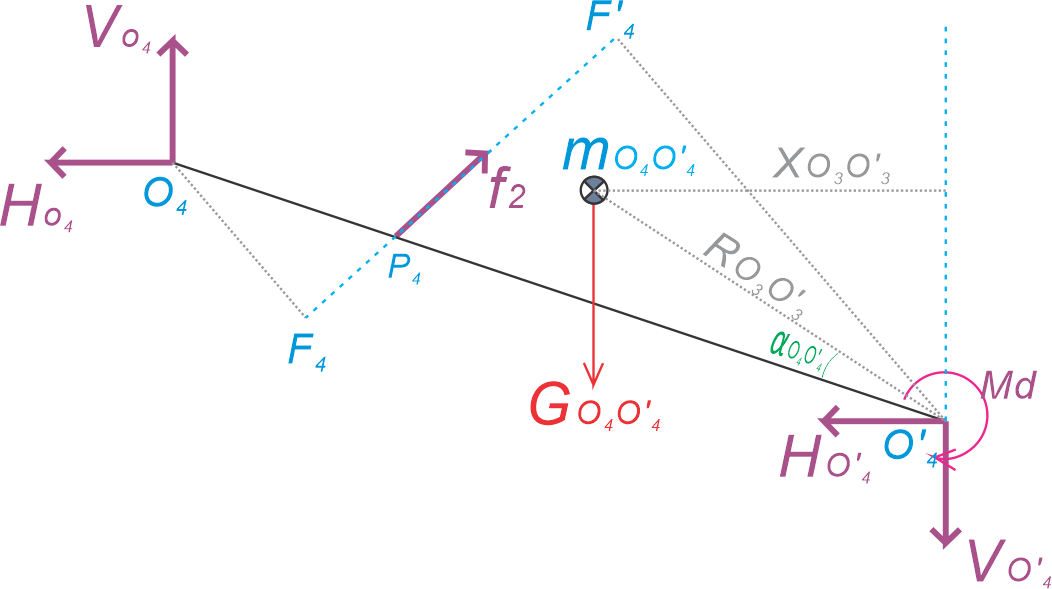

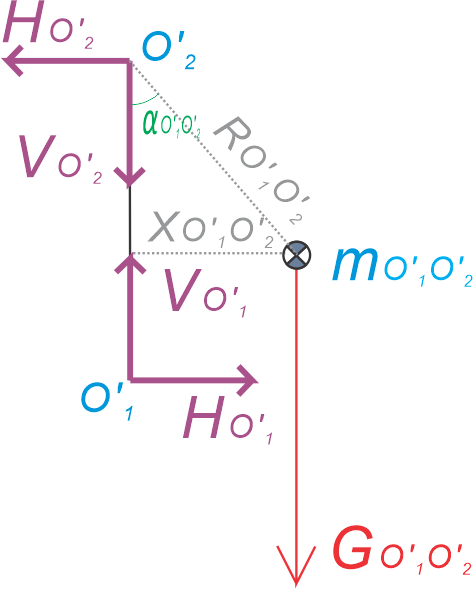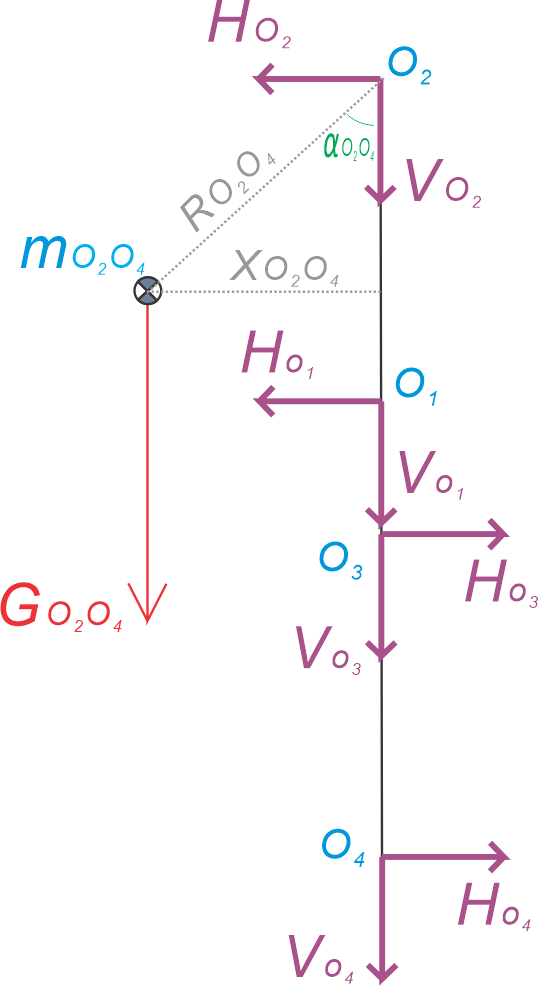


$$O_1 O_1^{\prime } :$$


RO1O_1=50; alphaO1O_1d = 15; %alpha in degree
mO1O_1.x = O1.x + RO1O_1 * cos(deg2rad(alphaO1O_1d) + thetar);
mO1O_1.y = O1.y + RO1O_1 * sin(deg2rad(alphaO1O_1d) + thetar);

$O_2 O_2^{\prime }$:

RO2O_2 = 50; alphaO2O_2d = 15;
mO2O_2.x = O2.x + RO2O_2 * cos(deg2rad(alphaO2O_2d) + thetar);
mO2O_2.y = O2.y + RO2O_2 * sin(deg2rad(alphaO2O_2d) + thetar);


$O_3 O_3^{\prime }$:

RO3O_3 = 50; alphaO3O_3d= 15;
mO3O_3.x = O_3.x - RO3O_3 * cos(deg2rad(alphaO3O_3d) + thetar);
mO3O_3.y = O_3.y - RO3O_3 + sin(deg2rad(alphaO3O_3d) + thetar);

$O_4 O_4^{\prime }$:

RO4O_4 = 50; alphaO4O_4d = 15;
mO4O_4.x = O_4.x - RO4O_4 * cos(deg2rad(alphaO4O_4d) + thetar);
mO4O_4.y = O_4.y + RO4O_4 * sin(deg2rad(alphaO4O_4d) + thetar);

$O_1^{\prime } O_2^{\prime }$:

RO_1O_2 = 20; alphaO_1O_2d = 15;
mO_1O_2.x = O_2.x + RO_1O_2 * sin(deg2rad(alphaO_1O_2d));
mO_1O_2.y = O_2.y - RO_1O_2 * cos(deg2rad(alphaO_1O_2d));

$O_2 O_4$:

RO2O4 = 20; alphaO2O4d = 15;
mO2O4.x = O2.x - RO2O4 * sin(deg2rad(alphaO2O4d));
mO2O4.y = O2.y - RO2O4 * cos(deg2rad(alphaO2O4d));